clear
clc
close all
format short g
syms s
sympref('TypesetOutput', true);
sympref('AbbreviateOutput', false);

opcionesControlador = ["P", "PI", "PID"];
opcionesMetodo = ["METODO 1", "METODO 2"];
opcionesFuente = ["GRAFICA", "FUNCION"];
opcionesPeriodo = ["DIRECTO", "DOS PICOS"];

controlador = opcionesControlador(3);

metodo = opcionesMetodo(2);

% grafica = ya tienes los valores
% funcion = te dan la funcion
fuente = opcionesFuente(2);


## Metodo 1

% Valores Metodo 1
K_m1 = 10;
L_m1 = .8;
P_m1 = 3.9;
% Funcion Metodo 1
G1_sym = exp(-1.5*s)/(s^2+3*s+2);

## **Metodo 2**

% Valor Kcr Metodo 2
Kcr_m2 = 1.8;

modoPeriodo = opcionesPeriodo(1);

% Valor Pcr, metodo 2 (directo)
Pcr_m2 = 1.6;

% Valor Pcr, metodo 2 (no sabes Pcr, pero si el val de dos picos)
tPico1_m2 = 2.6;
tPico2_m2 = 4.2;

% Funcion Metodo 2
G2_sym = 1/(s*(s + 1)*(s + 5));



tipo = upper(string(controlador));
metodo = upper(string(metodo));
fuente = upper(string(fuente));
modoPeriodo = upper(string(modoPeriodo));

%% validamos las selecciones

if ~ismember(tipo, opcionesControlador)
    error('controlador debe ser "P", "PI" o "PID".')
end

if ~ismember(metodo, opcionesMetodo)
    error('metodo debe ser "METODO 1" o "METODO 2".')
end

if ~ismember(fuente, opcionesFuente)
    error('fuente debe ser "GRAFICA" o "FUNCION".')
end

fprintf('Controlador: %s\n', char(tipo))

Controlador: PID


fprintf('Metodo: %s\n', char(metodo))

Metodo: METODO 2


fprintf('Fuente: %s\n', char(fuente))

Fuente: FUNCION


METODO 2: GANANCIA CRITICA
Funcion de transferencia recibida:


G =
 
          1
  -----------------
  s^3 + 6 s^2 + 5 s
 
Continuous-time transfer function.


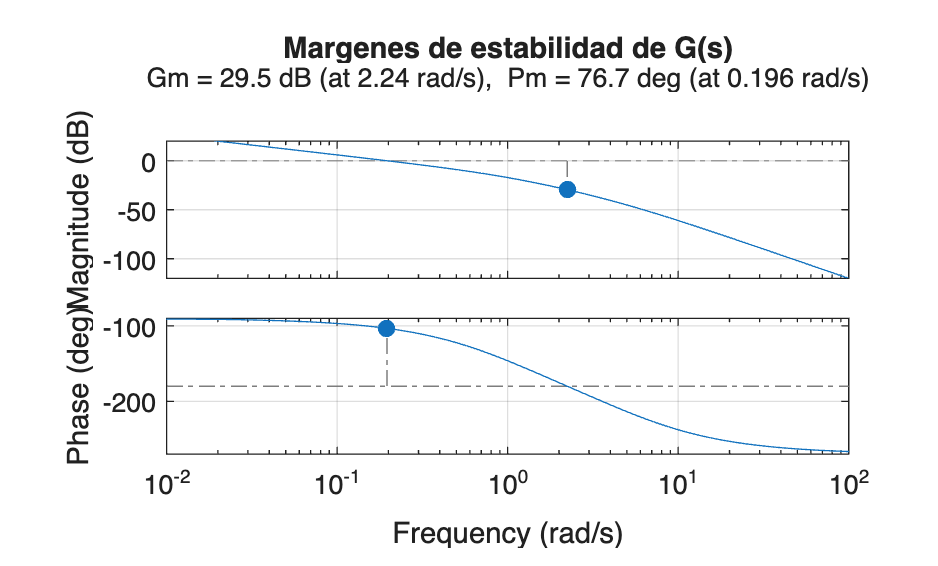

OBTENCION DE Kcr Y Pcr
1. Frecuencia critica:
Wcr = 2.236068 rad/s

2. Ganancia critica:
Kcr = margen de ganancia
Kcr = 30

3. Periodo critico:
Pcr = 2*pi/Wcr
Pcr = 2*pi/2.236068
Pcr = 2.8099259
PROCEDIMIENTO PASO A PASO: METODO 2
Datos utilizados:

Kcr = 30
Pcr = 2.8099259

De la tabla para controlador PID:

Kp = 0.6*Kcr
Kp = 0.6*30
Kp = 18

Ti = 0.5*Pcr
Ti = 0.5*2.8099259
Ti = 1.4049629

Td = 0.125*Pcr
Td = 0.125*2.8099259
Td = 0.35124074



%% llamamos el metodo seleccionado

if metodo == "METODO 1"

    datos.K = K_m1;
    datos.L = L_m1;
    datos.P = P_m1;
    datos.G_sym = G1_sym;

    [Kp, Ti, Td, G] = Metodo1zn( ...
        tipo, fuente, datos, s);

elseif metodo == "METODO 2"

    datos.Kcr = Kcr_m2;
    datos.Pcr = Pcr_m2;
    datos.modoPeriodo = modoPeriodo;
    datos.tPico1 = tPico1_m2;
    datos.tPico2 = tPico2_m2;
    datos.G_sym = G2_sym;

    [Kp, Ti, Td, G] = Metodo2zn( ...
        tipo, fuente, datos, s);
end


%% calculamos Ki y Kd

if isinf(Ti)
    Ki = 0;
else
    Ki = Kp/Ti;
end

Kd = Kp*Td;

fprintf('CALCULO DE Ki Y Kd\n')

CALCULO DE Ki Y Kd



switch tipo

    case "P"

        disp("El controlador P no utiliza accion integral:")

        displayFormula("K_i == 0")

        disp("El controlador P no utiliza accion derivativa:")

        displayFormula("K_d == 0")

    case "PI"

        disp("Calculo de la ganancia integral:")

        displayFormula("K_i == K_p/T_i")

        formula = sprintf( ...
            "K_i == %.8g/%.8g", ...
            Kp, Ti);

        displayFormula(formula)

        formula = sprintf( ...
            "K_i == %.8g", Ki);

        displayFormula(formula)

        disp("El controlador PI no utiliza accion derivativa:")

        displayFormula("K_d == 0")

    case "PID"

        disp("Calculo de la ganancia integral:")

        displayFormula("K_i == K_p/T_i")

        formula = sprintf( ...
            "K_i == %.8g/%.8g", ...
            Kp, Ti);

        displayFormula(formula)

        formula = sprintf( ...
            "K_i == %.8g", Ki);

        displayFormula(formula)

        disp("Calculo de la ganancia derivativa:")

        displayFormula("K_d == K_p*T_d")

        formula = sprintf( ...
            "K_d == %.8g*%.8g", ...
            Kp, Td);

        displayFormula(formula)

        formula = sprintf( ...
            "K_d == %.8g", Kd);

        displayFormula(formula)
end

Calculo de la ganancia integral:


$$K_{i}=\frac{K_{p}}{T_{i}}$$

$$K_{i}=\frac{18}{1.4049629}$$

$$K_{i}=12.811726$$

Calculo de la ganancia derivativa:


$$K_{d}=K_{p}\,T_{d}$$

$$K_{d}=18\,0.35124074$$

$$K_{d}=6.3223333$$


%% ecuacion del controlador

fprintf('ECUACION DEL CONTROLADOR %s\n', char(tipo))

ECUACION DEL CONTROLADOR PID



% Convertir los resultados numericos en numeros simbolicos.
Kp_s = numeroSimbolico(Kp);
Ki_s = numeroSimbolico(Ki);
Kd_s = numeroSimbolico(Kd);

if ~isinf(Ti)
    Ti_s = numeroSimbolico(Ti);
end

Td_s = numeroSimbolico(Td);

switch tipo

    %% CONTROLADOR P

    case "P"

        disp("PASO 1. Ecuacion general del controlador P:")

        displayFormula("G_c(s) == K_p")

        disp("PASO 2. Sustituir Kp:")

        formula = sprintf( ...
            "G_c(s) == %.8g", Kp);

        displayFormula(formula)

        disp("PASO 3. Controlador final:")

        formula = sprintf( ...
            "G_c(s) == %.8g", Kp);

        displayFormula(formula)

        Gc_s = Kp_s;
        Gc_tf = tf(Kp, 1);

    %% CONTROLADOR PI

    case "PI"

        disp("PASO 1. Ecuacion general del controlador PI:")

        displayFormula( ...
            "G_c(s) == K_p*(1 + 1/(T_i*s))")

        disp("PASO 2. Sustituir los valores uno por uno:")

        disp("Primero se sustituye Kp:")

        formula = sprintf( ...
            "G_c(s) == %.8g*(1 + 1/(T_i*s))", ...
            Kp);

        displayFormula(formula)

        disp("Ahora se sustituye Ti:")

        formula = sprintf( ...
            "G_c(s) == %.8g*(1 + 1/(%.8g*s))", ...
            Kp, Ti);

        displayFormula(formula)

        disp("PASO 3. Distribuir Kp:")

        displayFormula( ...
            "G_c(s) == K_p + K_p/(T_i*s)")

        formula = sprintf( ...
            "G_c(s) == %.8g + %.8g/(%.8g*s)", ...
            Kp, Kp, Ti);

        displayFormula(formula)

        disp("PASO 4. Utilizar la ganancia integral Ki:")

        displayFormula("K_i == K_p/T_i")

        formula = sprintf( ...
            "K_i == %.8g/%.8g", ...
            Kp, Ti);

        displayFormula(formula)

        formula = sprintf( ...
            "K_i == %.8g", Ki);

        displayFormula(formula)

        disp("Escribir el controlador en forma paralela:")

        displayFormula( ...
            "G_c(s) == K_p + K_i/s")

        formula = sprintf( ...
            "G_c(s) == %.8g + %.8g/s", ...
            Kp, Ki);

        displayFormula(formula)

        disp("PASO 5. Colocar todos los terminos sobre s:")

        displayFormula( ...
            "G_c(s) == (K_p*s + K_i)/s")

        formula = sprintf( ...
            "G_c(s) == (%.8g*s + %.8g)/s", ...
            Kp, Ki);

        displayFormula(formula)

        disp("Funcion de transferencia final del controlador PI:")

        formula = sprintf( ...
            "G_c(s) == (%.8g*s + %.8g)/s", ...
            Kp, Ki);

        displayFormula(formula)

        Gc_s = simplify( ...
            (Kp_s*s + Ki_s)/s);

        Gc_s = vpa(Gc_s, 8);

        Gc_tf = tf([Kp Ki], [1 0]);

    %% CONTROLADOR PID

    case "PID"

        disp("PASO 1. Ecuacion general del controlador PID:")

        displayFormula( ...
            "G_c(s) == K_p*(1 + 1/(T_i*s) + T_d*s)")

        disp("PASO 2. Sustituir los valores uno por uno:")

        disp("Primero se sustituye Kp:")

        formula = sprintf( ...
            "G_c(s) == %.8g*(1 + 1/(T_i*s) + T_d*s)", ...
            Kp);

        displayFormula(formula)

        disp("Ahora se sustituye Ti:")

        formula = sprintf( ...
            "G_c(s) == %.8g*(1 + 1/(%.8g*s) + T_d*s)", ...
            Kp, Ti);

        displayFormula(formula)

        disp("Finalmente se sustituye Td:")

        formula = sprintf( ...
            "G_c(s) == %.8g*(1 + 1/(%.8g*s) + %.8g*s)", ...
            Kp, Ti, Td);

        displayFormula(formula)

        disp("PASO 3. Distribuir Kp en cada termino:")

        displayFormula( ...
            "G_c(s) == K_p + K_p/(T_i*s) + K_p*T_d*s")

        formula = sprintf( ...
            "G_c(s) == %.8g + %.8g/(%.8g*s) + %.8g*%.8g*s", ...
            Kp, Kp, Ti, Kp, Td);

        displayFormula(formula)

        disp("PASO 4. Calcular Ki:")

        displayFormula("K_i == K_p/T_i")

        formula = sprintf( ...
            "K_i == %.8g/%.8g", ...
            Kp, Ti);

        displayFormula(formula)

        formula = sprintf( ...
            "K_i == %.8g", Ki);

        displayFormula(formula)

        disp("Calcular Kd:")

        displayFormula("K_d == K_p*T_d")

        formula = sprintf( ...
            "K_d == %.8g * %.8g", ...
            Kp, Td);

        displayFormula(formula)

        formula = sprintf( ...
            "K_d == %.8g", Kd);

        displayFormula(formula)

        disp("Escribir el controlador en forma paralela:")

        displayFormula( ...
            "G_c(s) == K_p + K_i/s + K_d*s")

        formula = sprintf( ...
            "G_c(s) == %.8g + %.8g/s + %.8g*s", ...
            Kp, Ki, Kd);

        displayFormula(formula)

        disp("PASO 5. Colocar todos los terminos sobre s:")

        displayFormula( ...
            "G_c(s) == (K_d*s^2 + K_p*s + K_i)/s")

        formula = sprintf( ...
            "G_c(s) == (%.8g*s^2 + %.8g*s + %.8g)/s", ...
            Kd, Kp, Ki);

        displayFormula(formula)

        disp("Funcion de transferencia final del controlador PID:")

        formula = sprintf( ...
            "G_c(s) == (%.8g*s^2 + %.8g*s + %.8g)/s", ...
            Kd, Kp, Ki);

        displayFormula(formula)

        Gc_s = simplify( ...
            (Kd_s*s^2 + Kp_s*s + Ki_s)/s);

        Gc_s = vpa(Gc_s, 8);

        Gc_tf = tf([Kd Kp Ki], [1 0]);
end

PASO 1. Ecuacion general del controlador PID:


$$G_{c}\left(s\right)=K_{p}\,\left(1+\frac{1}{T_{i}\,s}+T_{d}\,s\right)$$

PASO 2. Sustituir los valores uno por uno:


Primero se sustituye Kp:


$$G_{c}\left(s\right)=18\,\left(1+\frac{1}{T_{i}\,s}+T_{d}\,s\right)$$

Ahora se sustituye Ti:


$$G_{c}\left(s\right)=18\,\left(1+\frac{1}{1.4049629\,s}+T_{d}\,s\right)$$

Finalmente se sustituye Td:


$$G_{c}\left(s\right)=18\,\left(1+\frac{1}{1.4049629\,s}+0.35124074\,s\right)$$

PASO 3. Distribuir Kp en cada termino:


$$G_{c}\left(s\right)=K_{p}+\frac{K_{p}}{T_{i}\,s}+K_{p}\,T_{d}\,s$$

$$G_{c}\left(s\right)=18+\frac{18}{1.4049629\,s}+18\,0.35124074\,s$$

PASO 4. Calcular Ki:


$$K_{i}=\frac{K_{p}}{T_{i}}$$

$$K_{i}=\frac{18}{1.4049629}$$

$$K_{i}=12.811726$$

Calcular Kd:


$$K_{d}=K_{p}\,T_{d}$$

$$K_{d}=18\,0.35124074$$

$$K_{d}=6.3223333$$

Escribir el controlador en forma paralela:


$$G_{c}\left(s\right)=K_{p}+\frac{K_{i}}{s}+K_{d}\,s$$

$$G_{c}\left(s\right)=18+\frac{12.811726}{s}+6.3223333\,s$$

PASO 5. Colocar todos los terminos sobre s:


$$G_{c}\left(s\right)=\frac{K_{d}\,s^{2}+K_{p}\,s+K_{i}}{s}$$

$$G_{c}\left(s\right)=\frac{6.3223333\,s^{2}+18\,s+12.811726}{s}$$

Funcion de transferencia final del controlador PID:


$$G_{c}\left(s\right)=\frac{6.3223333\,s^{2}+18\,s+12.811726}{s}$$


%% resultados finales

fprintf('RESULTADO FINAL\n')

RESULTADO FINAL



fprintf('Controlador: %s\n', char(tipo))

Controlador: PID


fprintf('Metodo: %s\n\n', char(metodo))

Metodo: METODO 2




disp("Ganancia proporcional:")

Ganancia proporcional:



formula = sprintf("K_p == %.8g", Kp);
displayFormula(formula)

$$K_{p}=18$$


disp("Ganancia integral:")

Ganancia integral:



formula = sprintf("K_i == %.8g", Ki);
displayFormula(formula)

$$K_{i}=12.811726$$


disp("Ganancia derivativa:")

Ganancia derivativa:



formula = sprintf("K_d == %.8g", Kd);
displayFormula(formula)

$$K_{d}=6.3223333$$


disp("Tiempo integral:")

Tiempo integral:



if isinf(Ti)

    displayFormula("T_i == infinity")

else

    formula = sprintf("T_i == %.8g", Ti);
    displayFormula(formula)
end

$$T_{i}=1.4049629$$


disp("Tiempo derivativo:")

Tiempo derivativo:



formula = sprintf("T_d == %.8g", Td);
displayFormula(formula)

$$T_{d}=0.35124074$$


disp("Expresion simbolica final del controlador:")

Expresion simbolica final del controlador:



Gc_s

$$Gc\_s = \frac{6.3223333\,s^{2}+18.0\,s+12.811726}{s}$$


disp("Controlador como funcion de transferencia:")

Controlador como funcion de transferencia:



Gc_tf


Gc_tf =
 
  6.322 s^2 + 18 s + 12.81
  ------------------------
             s
 
Continuous-time transfer function.


SISTEMA EN LAZO CERRADO


Ecuacion general del sistema en lazo cerrado:


$$T_{c}\left(s\right)=\frac{G_{c}\left(s\right)\,G_{p}\left(s\right)}{1+G_{c}\left(s\right)\,G_{p}\left(s\right)}$$

Funcion de transferencia de lazo abierto:



G_lazo_abierto =
 
  6.322 s^2 + 18 s + 12.81
  ------------------------
    s^4 + 6 s^3 + 5 s^2
 
Continuous-time transfer function.


Funcion de transferencia de lazo cerrado:



G_lazo_cerrado =
 
         6.322 s^2 + 18 s + 12.81
  --------------------------------------
  s^4 + 6 s^3 + 11.32 s^2 + 18 s + 12.81
 
Continuous-time transfer function.


Polos del sistema controlado:


polos_controlados =       -4.1327 +          0i
     -0.37373 +     1.6213i
     -0.37373 -     1.6213i
      -1.1198 +          0i


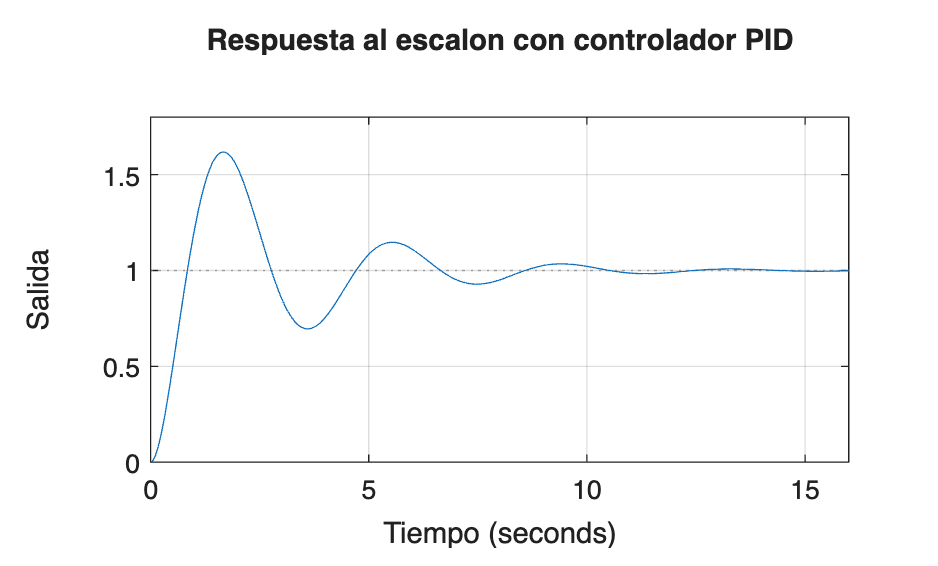


%% sistema del controlador en lazo cerrado

if ~isempty(G)
    fprintf('SISTEMA EN LAZO CERRADO\n')

    disp("Ecuacion general del sistema en lazo cerrado:")

    displayFormula( ...
        "T_c(s) == (G_c(s)*G_p(s))/(1 + G_c(s)*G_p(s))")

    try

        G_lazo_abierto = minreal(Gc_tf*G);
        G_lazo_cerrado = minreal(feedback(G_lazo_abierto, 1));

        disp("Funcion de transferencia de lazo abierto:")

        G_lazo_abierto

        disp("Funcion de transferencia de lazo cerrado:")

        G_lazo_cerrado

        disp("Polos del sistema controlado:")

        polos_controlados = pole(G_lazo_cerrado)

        figure
        step(G_lazo_cerrado)
        grid on

        title(['Respuesta al escalon con controlador ' char(tipo)])
        xlabel('Tiempo')
        ylabel('Salida')

    catch ME

        fprintf('No se pudo obtener la respuesta controlada.\n')
        fprintf('Mensaje de MATLAB: %s\n', ME.message)
    end
end



%% funciones locales

function valor_sym = numeroSimbolico(valor)
% Convierte un valor double en un numero simbolico.
% Evita que aparezcan muchos decimales causados por
% la representacion binaria de los numeros double.

    texto = sprintf('%.15g', valor);
    valor_sym = sym(texto);
end